# Aula 9 - Laboratório de Controle - 2022/1

## Modelagem e controle de modor CC

**Nomes:   **

if ~exist('obj')
    z=seriallist;
    comPort=z{length(z)};
    obj=serial(comPort,'BaudRate',9600);
    obj.Terminator='CR';
    fopen(obj);
end


**Atividade 1: Obtenção da resposta em malha aberta do motor CC**

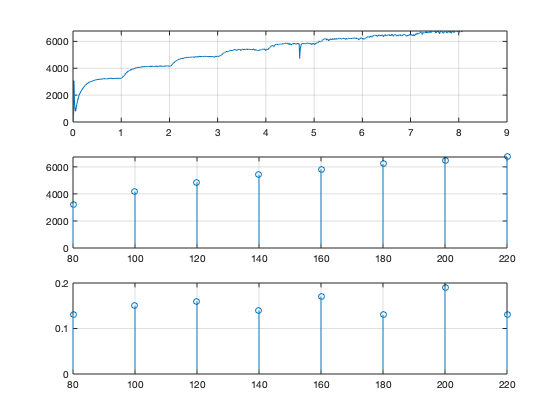

U0=[80:20:220]; % Escolher valores de sinal PWM a aplicar
Ts=10; % Tempo de amostragem em ms
Tempo=1; % Tempo de teste em segundos
[y,t,yr,tau] = arduino_coleta(obj,U0,Ts,Tempo);
figure
subplot(3,1,1);plot(t,y);title('Resposta ao degrau');grid;
subplot(3,1,2);stem(U0,yr);xlabel('U0');ylabel('RPM em regime');grid;

subplot(3,1,3);stem(U0,tau);xlabel('U0');ylabel('Const. tempo em s');grid;
zera_saida(obj);

1.1 Como se comporta o ganho  para diferentes velocidades do motor? Quais seus valores?

1.2 Como se comporta a constante de tempo  para diferentes velocidades do motor?

1.3 Qual a faixa de valores de entrada que podem ser aplicados e por que?

1.4 Como é feita a medição da velocidade do motor?

**Atividade 2: Obtenção do modelo do motor CC para um ponto de operação**

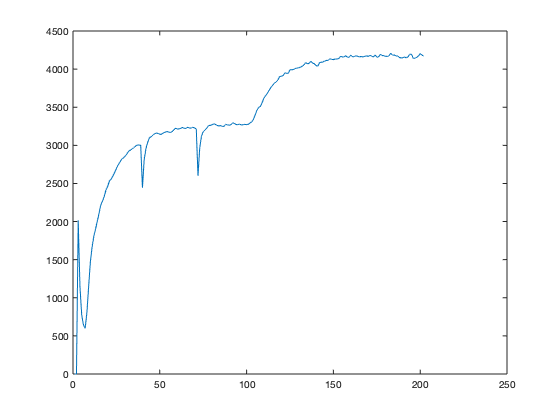

U0=[80  100]; % Escolher o ponto de operação aqui com o professor
[y,t,yr,tau] = arduino_coleta(obj,U0,Ts,Tempo);
figure;
plot(y);title('Resposta para a aplicação dos dois degraus em MA');
xlabel('Amostras');
zera_saida(obj);

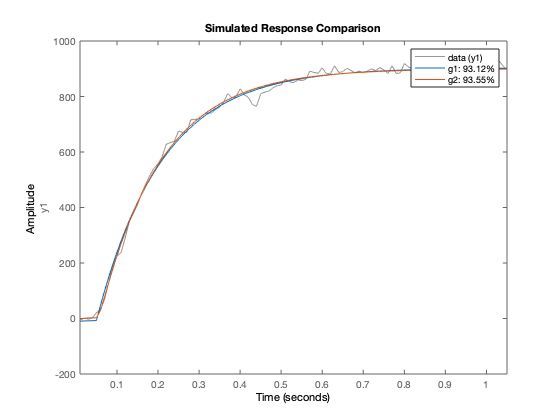

L=98; % Escolher a amostra a partir da qual obterá o modelo
y0=mean(y(L-5:L));
yf=mean(y(end-5:end));
yn=y(L:end)-y0;
K=(yf-y0)/(U0(2)-U0(1));
tau=(Ts/1000)*sum(yn<0.63*yn(end));
g=tf(K,[tau 1]);
N=floor(Tempo*1000/Ts);
U=zeros(length(y)-L+1,1);
U((end-N):end)=(U0(2)-U0(1));
t=(0:length(U)-1)*Ts/1000;
data=iddata(yn,U,Ts/1000);
g1=procest(data,'P1');
g2=procest(data,'P2');
figure;
compare(data,g1,g2);

2.1 Comente o ponto de operação escolhido e a qualidade dos dois modelos.

**Atividade 3: Controle do motor CC com controlador PI**

Escolher um valor adequado de lambda e testar o controlador PI projetado no mesmo ponto de operação usado para obter o modelo.

K=0; % Obter de g1
tau=0; % Obter de g1
Ts=10;
Tempo=2;
lambda=tau/5;
Kp=tau/(K*lambda); % Sintonia lambda
Ki=1/tau;

Ref0=500; % Escolher observando a resposta aos degraus da atividade 2
Ref=600;

[y,u,t] = arduino_controle(obj,Ref,Ts,Tempo, Kp, Ki, Ref0);
zera_saida(obj);
figure;

subplot(2,1,1);
r=Ref*ones(size(y));
stairs(t,[y r]);title('Saida');
subplot(2,1,2);
stairs(t,u);title('Controle');


3.1 Qual a resposta mais rápida que conseguiu e qual foi a limitação?

3.2 Obtenha uma  resposta que considere boa e informe os ganhos do controlador, sobreelevação, tempo de estabelecimento, erro em regime.

3.3 Teste o  controlador de 3.2 em outros pontos de operação (mude Ref e Ref0, sendo Ref>Ref0) e comente o que observou, justificando.